se3.hat(rand([6, 1]))

ans =          0   -0.0975    0.6324    0.8147
    0.0975         0   -0.9134    0.9058
   -0.6324    0.9134         0    0.1270
         0         0         0         0


% Construct the button pushing trajectory?
g_arm_base = SE2.hat([0, 0, -pi/2]);
default_length_of_link = 1;

traj_start_pose = SE2.hat([-1.5, -1.5, pi]);
traj_end_pose = SE2.hat([-2, -2, pi]);

se2.expm(se2.hat([1.5, 0, pi/2]))

ans =          0   -1.0000    0.9549
    1.0000         0    0.9549
         0         0    1.0000


syms theta_ab l_ab

se2.expm(se2.hat([l_ab, 0, theta_ab]))

$$ans = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{ab}}\right) & -\sin\left(\theta_{\mathrm{ab}}\right) & \frac{l_{\mathrm{ab}}\,\sin\left(\theta_{\mathrm{ab}}\right)}{\theta_{\mathrm{ab}}}\\ \sin\left(\theta_{\mathrm{ab}}\right) & \cos\left(\theta_{\mathrm{ab}}\right) & -\frac{l_{\mathrm{ab}}\,\left(\cos\left(\theta_{\mathrm{ab}}\right)-1\right)}{\theta_{\mathrm{ab}}}\\ 0 & 0 & 1 \end{array}\right)$$

syms l gamma kappa
vars_shearing_expm = [l, gamma, kappa];
assume(vars_shearing_expm, "real")

se2.expm(se2.hat([l, gamma, kappa]))

$$ans = \left(\begin{array}{ccc} \cos\left(\kappa \right) & -\sin\left(\kappa \right) & \frac{l\,\sin\left(\kappa \right)}{\kappa }+\frac{\gamma \,\left(\cos\left(\kappa \right)-1\right)}{\kappa }\\ \sin\left(\kappa \right) & \cos\left(\kappa \right) & \frac{\gamma \,\sin\left(\kappa \right)}{\kappa }-\frac{l\,\left(\cos\left(\kappa \right)-1\right)}{\kappa }\\ 0 & 0 & 1 \end{array}\right)$$

syms theta_ab theta_bc theta_cd l_ab l_bc l_cd
vars = [theta_ab, theta_bc, theta_cd, l_ab, l_bc, l_cd];
assume(vars, "Real")

g_ab = se2.expm(se2.hat([l_ab, 0, theta_ab]));
g_bc = se2.expm(se2.hat([l_bc, 0, theta_bc]));
g_cd = se2.expm(se2.hat([l_cd, 0, theta_cd]));

% Analytic form of the space of end-effector poses which are arrived at by
% constant shear-free twist.
g_end = g_arm_base * g_ab * g_bc * g_cd

$$g\_end = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & \cos\left(\theta_{\mathrm{cd}}\right)\,\sigma_{2}-\sin\left(\theta_{\mathrm{cd}}\right)\,\sigma_{3} & \frac{l_{\mathrm{cd}}\,\sin\left(\theta_{\mathrm{cd}}\right)\,\sigma_{3}}{\theta_{\mathrm{cd}}}-\frac{l_{\mathrm{ab}}\,\left(\cos\left(\theta_{\mathrm{ab}}\right)-1\right)}{\theta_{\mathrm{ab}}}+\frac{l_{\mathrm{bc}}\,\sin\left(\theta_{\mathrm{ab}}\right)\,\sin\left(\theta_{\mathrm{bc}}\right)}{\theta_{\mathrm{bc}}}-\frac{l_{\mathrm{cd}}\,\left(\cos\left(\theta_{\mathrm{cd}}\right)-1\right)\,\sigma_{2}}{\theta_{\mathrm{cd}}}-\frac{l_{\mathrm{bc}}\,\cos\left(\theta_{\mathrm{ab}}\right)\,\left(\cos\left(\theta_{\mathrm{bc}}\right)-1\right)}{\theta_{\mathrm{bc}}}\\ \sin\left(\theta_{\mathrm{cd}}\right)\,\sigma_{3}-\cos\left(\theta_{\mathrm{cd}}\right)\,\sigma_{2} & \sigma_{1} & -\frac{l_{\mathrm{ab}}\,\sin\left(\theta_{\mathrm{ab}}\right)}{\theta_{\mathrm{ab}}}-\frac{l_{\mathrm{cd}}\,\sin\left(\theta_{\mathrm{cd}}\right)\,\sigma_{2}}{\theta_{\mathrm{cd}}}-\frac{l_{\mathrm{bc}}\,\cos\left(\theta_{\mathrm{ab}}\right)\,\sin\left(\theta_{\mathrm{bc}}\right)}{\theta_{\mathrm{bc}}}-\frac{l_{\mathrm{cd}}\,\left(\cos\left(\theta_{\mathrm{cd}}\right)-1\right)\,\sigma_{3}}{\theta_{\mathrm{cd}}}-\frac{l_{\mathrm{bc}}\,\sin\left(\theta_{\mathrm{ab}}\right)\,\left(\cos\left(\theta_{\mathrm{bc}}\right)-1\right)}{\theta_{\mathrm{bc}}}\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{\mathrm{cd}}\right)\,\sigma_{3}+\sin\left(\theta_{\mathrm{cd}}\right)\,\sigma_{2}\\ \sigma_{2}=\cos\left(\theta_{\mathrm{ab}}\right)\,\cos\left(\theta_{\mathrm{bc}}\right)-\sin\left(\theta_{\mathrm{ab}}\right)\,\sin\left(\theta_{\mathrm{bc}}\right)\\ \sigma_{3}=\cos\left(\theta_{\mathrm{ab}}\right)\,\sin\left(\theta_{\mathrm{bc}}\right)+\cos\left(\theta_{\mathrm{bc}}\right)\,\sin\left(\theta_{\mathrm{ab}}\right) \end{array}$$

$$ans = \left(\begin{array}{ccc} \cos\left(\kappa \right) & -\sin\left(\kappa \right) & \frac{l\,\sin\left(\kappa \right)}{\kappa }+\frac{\gamma \,\left(\cos\left(\kappa \right)-1\right)}{\kappa }\\ \sin\left(\kappa \right) & \cos\left(\kappa \right) & \frac{\gamma \,\sin\left(\kappa \right)}{\kappa }-\frac{l\,\left(\cos\left(\kappa \right)-1\right)}{\kappa }\\ 0 & 0 & 1 \end{array}\right)$$

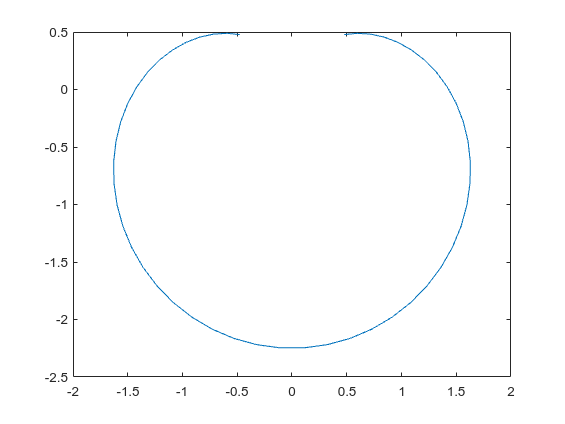

% Sweep this for a range of possible theta and l values to sample the
% workspace?
l_range = [0.75, 0.75];
theta_range = [-pi/2, pi/2];

n_samples = 50;
ls = reshape(linspace(l_range(1), l_range(2), n_samples), [1, 1, n_samples]);
thetas = reshape(linspace(theta_range(1), theta_range(2), n_samples), [1, 1, n_samples]);

struct_vals = struct();
struct_vals.theta_ab = thetas;
struct_vals.theta_bc = thetas;
struct_vals.theta_cd = thetas;
struct_vals.l_ab = ls;
struct_vals.l_bc = ls;
struct_vals.l_cd = ls;

poses_sampled = double(vpa(subs(g_end, struct_vals)));

xs = poses_sampled(1, 3, :);
ys = poses_sampled(2, 3, :);

plot(xs(:), ys(:))